#  最小噪声方差准则(Minimum Variance Distortless Response,MVDR/Capon)

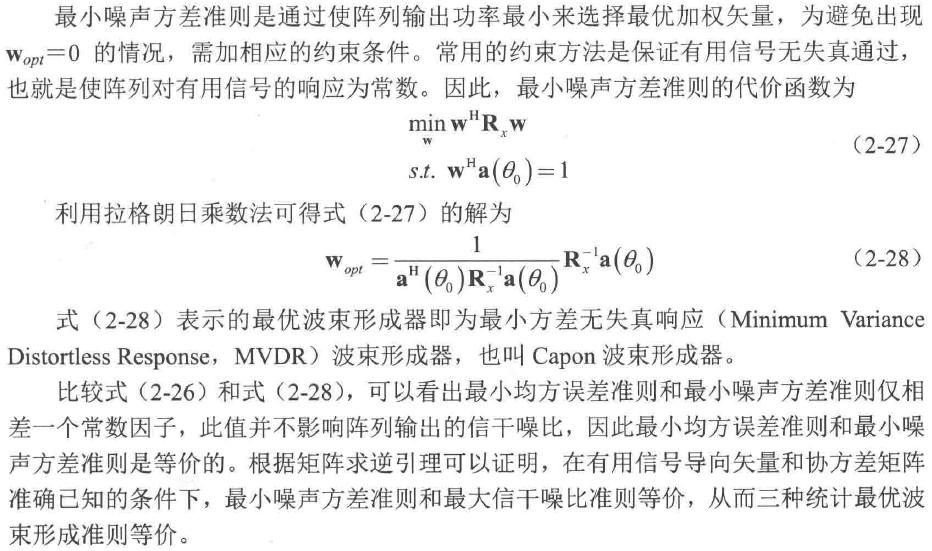

**已知：信号的来向**

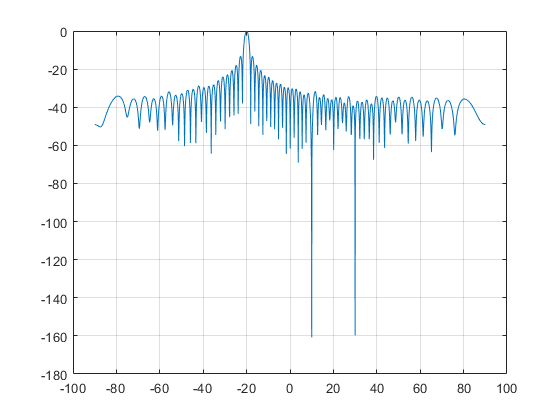

%--------------------------------------------------------------------------
%   初始化
%--------------------------------------------------------------------------
clear;clc;

%--------------------------------------------------------------------------
%   参数设置
%--------------------------------------------------------------------------
N = 64;                                                                      %阵元个数
theta = [-20 10 30];                                                        %信号 干扰 干扰
angle_axis = -90:0.1:90;
M = numel(theta);                                                           %信源个数
snr = 100;                                                                   %信噪比
K = 100000;                                                                   %采样点数

%--------------------------------------------------------------------------
%   生成3个来向的导向矢量
%--------------------------------------------------------------------------
c = 3e8;                                                                    %光速
lambda = 1;                                                                 %波长
dd = lambda/2;                                                              %阵元间距d = lambda/2
d = 0:dd:(N-1)*dd;                                                          %构建阵列坐标
A = exp(1j.*2*pi*d.'*sind(theta));                                          %构建阵列流形

%--------------------------------------------------------------------------
%   接收信号为随机值
%   并按照阵列流形构造回波相位                                  
%--------------------------------------------------------------------------
S = randn(M,K) + 1j.*randn(M,K);                                            %构建接收信号

%--------------------------------------------------------------------------
%   构建干扰信号的协方差矩阵
%--------------------------------------------------------------------------
X = A(:,2:end)*S(2:end,:);                                                  %构造接收信号模型
X1 = awgn(X,snr,'measured');
%--------------------------------------------------------------------------
%   最优导向矢量w_opt为R_jn中最大特征值对应的特征向量，即为
%   w_opt = y*R_jn^-1*a(theta_0)
%--------------------------------------------------------------------------
R_x = X1*X1';                                                              %协方差矩阵

w_opt = R_x^-1*A(:,1)./(A(:,1)'*R_x^-1*A(:,1));


%--------------------------------------------------------------------------
%   绘制天线方向图
%--------------------------------------------------------------------------
[~,~,L_dB] = L_norm_array_pattern(w_opt,angle_axis);


figure(1)
plot(angle_axis,L_dB);grid on;